# Diffusion as a Random Walk - in 1D and 2D

Diffusion is characterized by random movements in time.  Due to the characteristics of diffusive movement (also referred to as Brownian motion), it is effectively captured in a **Monte Carlo **simulation.  The Monte Carlo approach uses random number generators and probability to simulate the movement of a molecule in each dimension.

## Random number generators

Before we get into the details of how to dimulate diffusion, it is important to note that so-called "random number generators" are *not truly random**, *but rather are a reproducible sequence of numbers that have properties of being random.  A simple example of a random number generator is 

Eq. 1.1                                                 $X_n =\mathrm{mod}\left(aX_{n-1} +b,m\right)$

where *a*, *b*, and *m *are large integers.  The modulo operation ($\mathrm{mod}\left(i,j\right)$) returns the remainder after dividing $i$by $j$.  An example of how this might be coded is below

a = 7^3; %integer value
b = 5^4; %integer value
m = 2^16; %integer value
X = zeros(10,1); %generate a total of 10 numbers in the sequence
X(1) = 2^14; %intialize the sequence
for n = 2:numel(X)
    X(n) = mod(a*X(n-1)+b,m); %modulo operation to find the remainder, Eq. 1.1
end
disp(X)

       16384
       49777
       34776
        1241
       33072
        6593
       33800
       59689
       26720
       56081



This sequence will generate a total of *m*-1 numbers, if we want the $X_n$ to be between 0 and 1, then we can divide by *m*-1. 

X = X/(m-1)

Conveniently, MATLAB (as well as other programming languages) has built-in random number generators that return numbers from a  sequence that captures the statistics of different distributions.  

rand %random numbers from a uniform distribution on the scale [0,1]

ans = 0.8147

randn %random numbers from a standard normal (Gaussian) distribution (mean = 0, standard deviation = 1)

ans = 1.8339

While the generators can effectively produce numbers with the statistics of being random, this means that an identical sequence of numbers is generated when the sequence is started in the same position.  

seed = 100; %seed that tells the generator where to start in the sequence
rng(seed) %function that initializes the generator using the "seed" value

rand(5,1) % generate a 5 x 1 array of random numbers

ans =     0.5434
    0.2784
    0.4245
    0.8448
    0.0047


Using the same seed to initialize the random number generator will produce the same sequence of numbers

seed = 100; %seed to initialize
rng(seed); %initialize random number generator
temp1 = rand(1000,1); %generate 1000 numbers
rng(seed); %re-initialize with the same seed
temp2 = rand(1000,1); %generate 1000 numbers
isequal(temp1,temp2) %check to see if the two sequences are exactly equal

ans = logical
   1


Everytime you startup MATLAB, the built-in random number generators are initiated with the same seed.  This means that if you generate a sequence of random numbers, close MATLAB, and reopen you will then generate the identical sequence of numbers.

A convenient way to avoid this is to shuffle the seed based on the current CPU time.

rng('shuffle') %shuffle the random number generators using the CPU clock

It is a good practice to put this line of code at the beginning of your scripts when using random number generators in a Monte Carlo approach

## 1D Random Walk

Using a Monte Carlo approach, and random number generators, let's simulate the diffusion of a spherical protein having MW = 150 kg/mol (kDa) and density = 1400 kg/m^3, assuming the viscosity of the cytoplasm is 0.005 kg/(m*s) and the temperature is 310 K.  Simulate for 1000 seconds using a time step of 1 sec.

The volume of a sphere is given by 

Eq. 1.2                                            $V=\frac{4}{3}\pi R^3 =\frac{m}{\rho }$

where $R$ is the radius of the sphere and $m$ and $\rho$ are the mass and density, respectively.  The diffusion coefficient is thermal energy divided by the drag coefficient, which for a sphere is

Eq. 1.3                                           $D=\frac{k_B T}{\gamma }=\frac{k_B T}{6\pi \eta R}$ 

where $k_B$ is Boltzmann's constant, $T$ is absolute temperature, and $\eta$ is the viscosity of the fluid.  

Based on our time step, we can solve for a corresponding step size using the expected mean-squared displacement (MSD).  Remember, in a single dimension

Eq. 1.4                                              $\left\langle x^2 \left(t\right)\right\rangle =2\mathit{Dt}$

The step size in time $\Delta t$ comes from taking the square root of the MSD, so-called root-mean-squared displacement (rMSD).

We can use the equations above to calculate and assign the parameter values to use in the simulation.

% assign parameter values
MW = 150; %kg/mol (kDa), molecular weight
density = 1400; %kg/m^3, density
visc = 0.005; %kg/m*s, viscosity of the fluid
T = 310; %K, absolute temperature (37 deg C)
kB = 1.381e-23; %J/K, Boltzmann's constant
N_A = 6.022e23; %mol^-1, Avogadro's number, number of molecules in one mole

dt = 1; %s, time step for simulation
Nsteps = 1000; % total number of steps to simulate
Nmolec = 1; %number of molecules to simulate

% solve for other parameters
R = ((3*MW)/(4*density*pi*N_A))^(1/3) %m, spherical radius of a single molecule by solving for r in Eq. 1.2

R = 3.4891e-09

D = (kB*T)/(6*pi*visc*R) %m^2/s, diffusion coefficient from Eq. 1.3

D = 1.3019e-11

dx = sqrt(2*D*dt) %m, diffusive step size in one dimension from the root-mean-squared displacement, Eq 1.4

dx = 5.1027e-06

Initializing arrays increases the speed of simulation.  MATLAB is column oriented, which means that indexing down a column is faster than indexing across the rows

xpos = zeros(Nsteps,1); % molecule position
time = zeros(Nsteps,1); % time

Now that we have all the parameters and have initialized our arrays, we are ready to implement the steps to simulate diffusion in one dimension.  For each simulation step, we need to 

- generate a random number

- determine if step is to the right or left (coin flip)

- update position

- update time.

for i = 2:Nsteps %loop through each step of the simulation
    temp = rand; %flip a coin, generate a uniformly distributed random number
    if temp<=0.5 %determine if the step is to the right or left, equal probability of stepping in either direction
        xpos(i) = xpos(i-1)+dx; %step to the right
    else
        xpos(i) = xpos(i-1)-dx; %step to the left
    end
    time(i)=time(i-1)+dt; % update time
end
fpos = xpos(end); %record final position

Let's view the resulting trajectory.

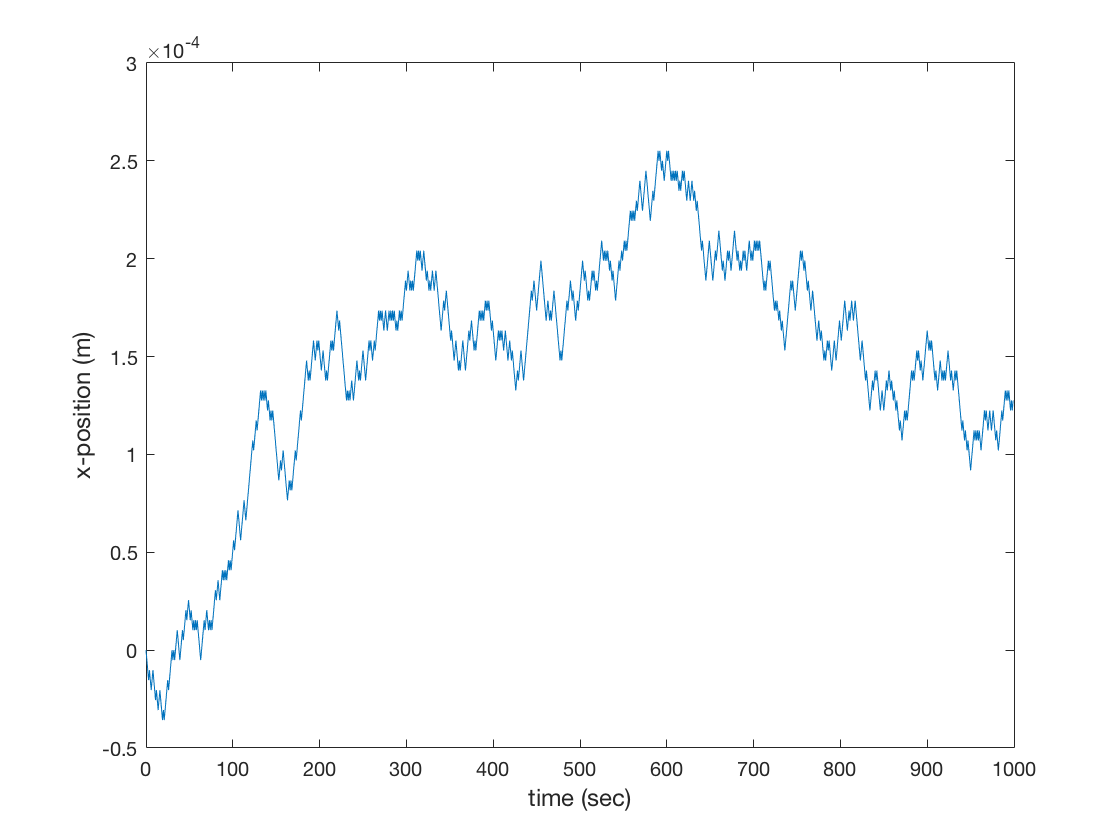

figure(1);clf
plot(time,xpos)
xlabel('time (sec)','FontSize',12)
ylabel('x-position (m)','FontSize',12)

To get an idea of how the molecules spread from a point source in time let's simulate 1000 trajectories of the same simulation.  Diffusion from a point source obeys a Gaussian distribution where the probability of being at position $x$ at time $t$ is given by

Eq. 1.5                                $p\left(x,t\right)=\frac{1}{\sqrt{2\pi \sigma^2 }}\mathrm{exp}\left(\frac{-{\left(x-\mu \right)}^2 }{2\sigma^2 }\right)$

with the mean $\mu =0$ and variance $\sigma^2 =\text{MSD}=2\mathit{\text{Dt}}$.  This means that while the population spreads in time ($\sigma^2 =2\mathit{Dt}$), on average an individual molecule does not go anywhere ($\mu =0$)!

% initialize arrays
Nmolec = 100; % number of molecules to simulate
xpos = zeros(Nsteps,1); % molecule position
time = zeros(Nsteps,1); % time
fpos = zeros(Nmolec,1); % final positions of each molecule

% simulate for each molecule
for n = 1:Nmolec % loop over the number of molecules
    for i = 2:Nsteps % loop through all steps of the simulation
        temp = rand; % generate a uniformly distributed random number
        if temp<=0.5 % determe if the step is to the right or left, equal probability of stepping in either direction
            xpos(i) = xpos(i-1)+dx; %step to the right
        else
            xpos(i) = xpos(i-1)-dx; %step to the left
        end
        time(i)=time(i-1)+dt; % update time
    end
    fpos(n) = xpos(end); % gather final positions for each molecule
end

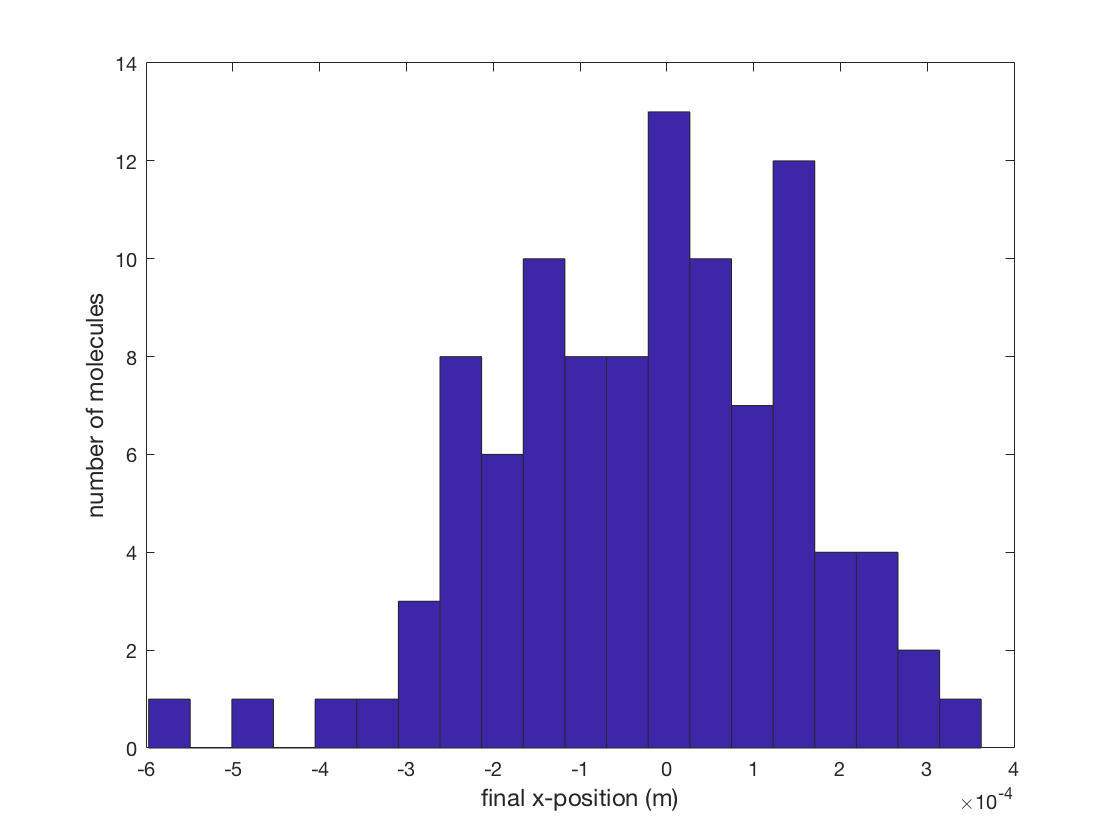

%plot results
figure(2);clf
hist(fpos,20)
xlabel('final x-position (m)','FontSize',12)
ylabel('number of molecules','FontSize',12)

Do the distribution statistics fit with the theoretically expected values?

distMean = mean(fpos) %mean of the distribution of molecules

distMean = -2.5616e-05

distVar = var(fpos) %variance of the distribution of molecules

distVar = 3.1192e-08

theoVar = 2*D*(dt*Nsteps) % mean-squared-displacement value for the diffusive molecule, from Eq. 1.4

theoVar = 2.6038e-08

## 2D Random Walk

Now let's take what we've done above for 1-dimension and expand into multiple dimensions by simulating the diffusion of the same protein in 2-dimensions.  Once we have worked out the simulation procedure for a single dimension, expanding dimensionality is relatively straight forward.  We need to simply repeat the random stepping (coin flip) in each dimension.  

% initialize arrays for each dimension and time
xpos = zeros(Nsteps,1); % molecule x-position
ypos = zeros(Nsteps,1); % molecule y-position
time = zeros(Nsteps,1); % time

for i = 2:Nsteps %loop through the total number of simulation steps
    temp = rand; %generate a uniformly distributed random number
    %stepping in the x-dimension
    if temp<=0.5
        xpos(i) = xpos(i-1)+dx; %step to the right
    else
        xpos(i) = xpos(i-1)-dx; %step to the left
    end
    %stepping in the y-dimension
    temp = rand; %generate a second random number
    if temp<=0.5
        ypos(i) = ypos(i-1)+dx; %step up
    else
        ypos(i) = ypos(i-1)-dx; %step down
    end
    time(i)=time(i-1)+dt; %advance time
end

That's it! Let's view the resulting trajectory.

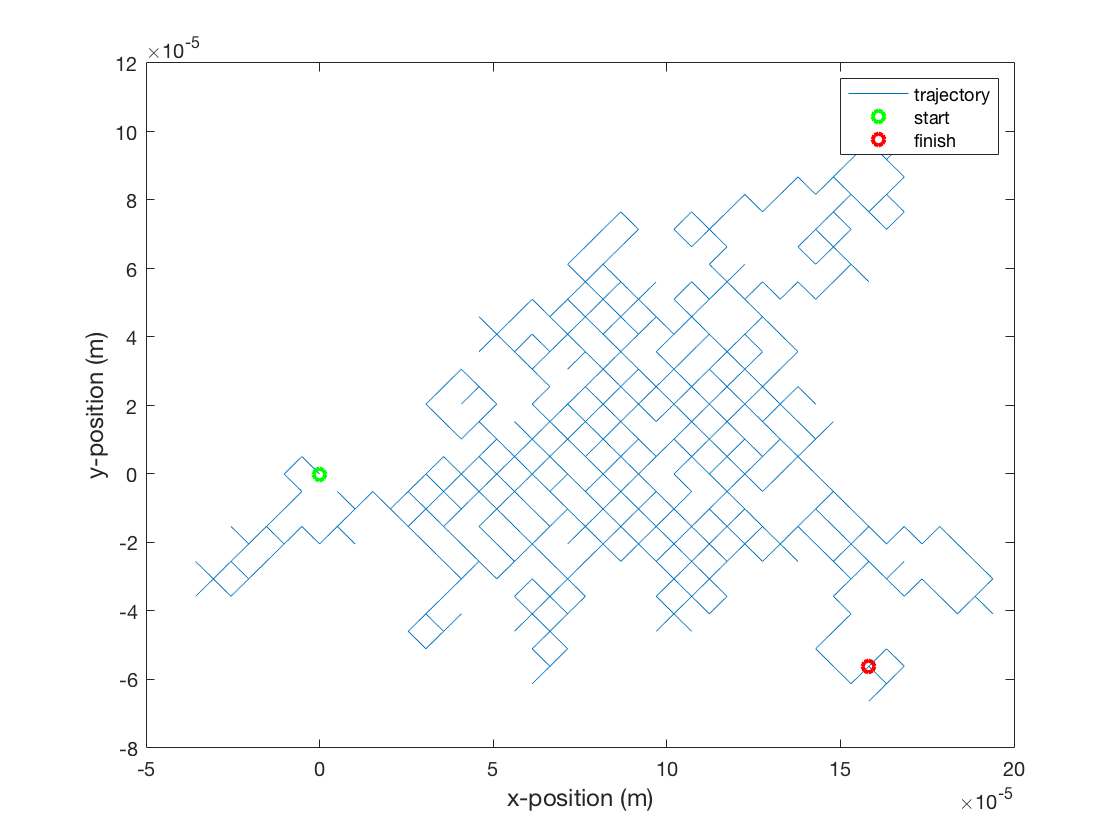

figure(3);clf
plot(xpos,ypos);hold on;
plot(xpos(1),ypos(1),'go','LineWidth',2)
plot(xpos(end),ypos(end),'ro','LineWidth',2)
xlabel('x-position (m)','FontSize',12)
ylabel('y-position (m)','FontSize',12)
legend('trajectory','start','finish')

Remember for a random walk in multi-dimensions

Eq. 1.5                                $\left\langle r^2 \right\rangle =2\mathit{\text{dDt}}$ 

where $d$ is the dimensionality coefficient.  However, in the simulation above we used the root-mean-squared displacement (rMSD) for a single dimension.  Why is that? 

Keep in mind where the value of $d$ comes from.

in 2-dimensions $r^2 =\delta^2 +\delta^2 =2\delta^2$

in 3-dimensions $r^2 =\delta^2 +\delta^2 +\delta^2 =3\delta^2$

Therefore, the value that is used for the step size in the simulation will depend on how the steps are implemented at each time point.  As above, when implementing a step in each dimension, for each time point, we used the step size from a single dimension $\delta$.  The dimensionality coefficient $d$ naturally comes out of how the displacement $r$ is calculated in multiple dimensions. 

To confirm that this is the case, let's again simulate 1000 trajectories and examine the distribution of positions at the end of 1000 sec. 

%initialize arrays
Nmolec = 100; %number of molecules to simulate
xpos = zeros(Nsteps,1); % molecule position
ypos = zeros(Nsteps,1); % molecule position
time = zeros(Nsteps,1); % time
fxpos = zeros(Nmolec,1); % final x-positions of each molecule
fypos = zeros(Nmolec,1); % final y-positions of each molecule

%simulate for each molecule
for n = 1:Nmolec
    for i = 2:Nsteps
        temp = rand; %generate a uniformly distributed random number
        %stepping in the x-dimension
        if temp<=0.5
            xpos(i) = xpos(i-1)+dx; %step to the right
        else
            xpos(i) = xpos(i-1)-dx; %step to the left
        end
        %stepping in the y-dimension
        temp = rand; %generate a second random number
        if temp<=0.5
            ypos(i) = ypos(i-1)+dx; %step up
        else
            ypos(i) = ypos(i-1)-dx; %step down
        end
        time(i)=time(i-1)+dt;
    end
    fxpos(n) = xpos(end); %gather final positions for each molecule
    fypos(n) = ypos(end); 
end

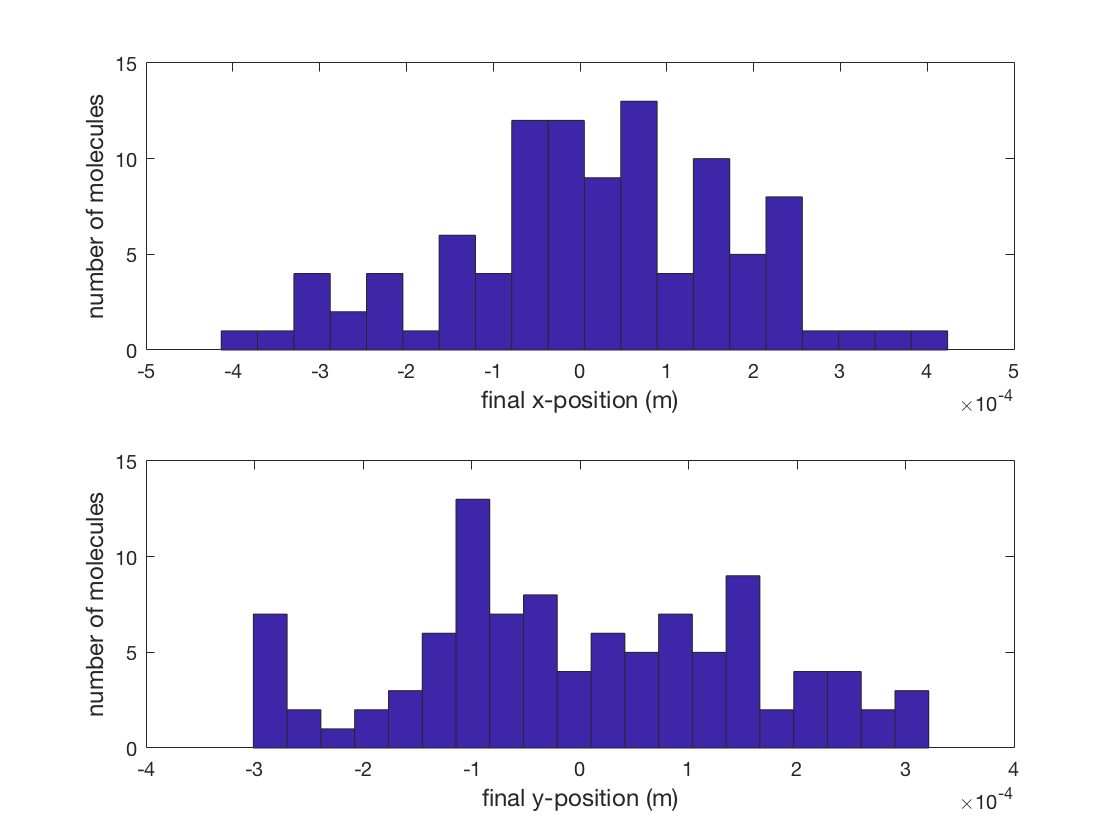

%plot the results
figure(4);clf
subplot(2,1,1)
hist(fxpos,20)
xlabel('final x-position (m)','FontSize',12)
ylabel('number of molecules','FontSize',12)
subplot(2,1,2)
hist(fypos,20)
xlabel('final y-position (m)','FontSize',12)
ylabel('number of molecules','FontSize',12)

Do the distribution statistics fit with the theoretically expected values?  They should if we've used the correct step size.

xVar = var(fxpos) %variance of the x-positions

xVar = 2.6465e-08

yVar = var(fypos) %variance of the y-positions

yVar = 2.4224e-08


theo_msd_1D = 2*D*(dt*Nsteps)

theo_msd_1D = 2.6038e-08

msd_2D = mean(fxpos.^2+fypos.^2) %mean squared displacement from simulation

msd_2D = 5.0390e-08


theo_msd_2D = 2*2*D*(dt*Nsteps) % mean-squared-displacement value for the diffusive molecule

theo_msd_2D = 5.2075e-08